## Robustness Margins and Disk Margins

### - Akash Sharma and Yash Malandkar

### Exercise - 1

- We cannot say for sure if the system is closed-loop unstable just by looking at its negative gain margin. The gain margin signifies critical points through which the poles will cross the imaginary axis. The poles can cross from positive to negative or vica-versa. Therefore it cannot be said if the system is getting stable or unstable.We would have to look at the root locus plots to visualizes what is going on.

- We cannot say for sure if the system is closed-loop unstable just by looking at its negative phase margin. The gain margin signifies critical points through which the poles will cross the imaginary axis. The poles can cross from positive to negative or vica-versa. Therefore it cannot be said if the system is getting stable or unstable.We would have to look at the root locus plots to visualizes what is going on

- We cannot say for sure if the system is closed-loop stable even if MATLAB's allmargin() returns positive gain margins. Similar to the fact that we cannot ensure unstability by looking at nagative gain or phase margins, we also cannot ensure stablity looking at positve gain margins.

### Exercise - 2

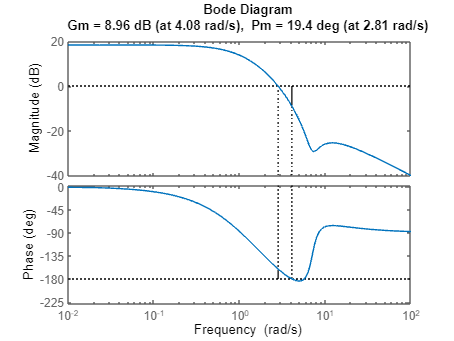

clear all
clc
close all

s = tf('s');

L = (s^2 + 2*s + 50)/(s^3 + 6*s^2 + 11*s + 6);

% Classical gain and phase margins
margin(L)

allmargin(L)

ans = struct with fields:
     GainMargin: [2.8051 10.6934]
    GMFrequency: [4.0756 5.6910]
    PhaseMargin: 19.3948
    PMFrequency: 2.8149
    DelayMargin: 0.1203
    DMFrequency: 2.8149
         Stable: 1



% Disk-based gain and phase margins
diskmargin(L)

ans = struct with fields:
           GainMargin: [0.7313 1.3675]
          PhaseMargin: [-17.6461 17.6461]
           DiskMargin: 0.3104
           LowerBound: 0.3104
           UpperBound: 0.3104
            Frequency: 2.9647
    WorstPerturbation: [1×1 ss]


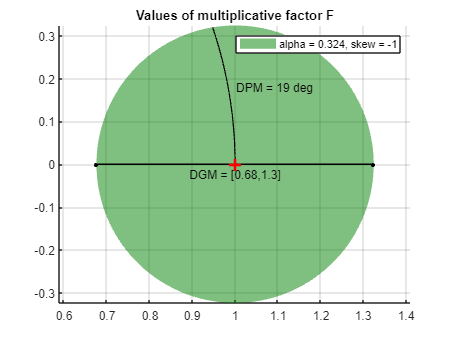


% T-Based Disk Margin
sigma = -1;
T = feedback(L,1);
alpha = inv(norm(T,Inf));
diskmarginplot(alpha,sigma,'disk')

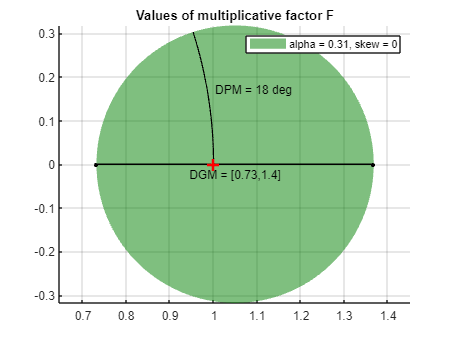


% S-T balanced (symmetric) disk margin
sigma = 0;
S = 1-T;
alpha = inv(0.5*norm(S-T,Inf));
diskmarginplot(alpha,sigma,'disk')

**4. Since all the Nyquist points for the uncertitude fall inside our T-based and S-T based disk margins, it is safe to say that the system is robustly stable in view of real-life uncertainities.**

### Exercise 3

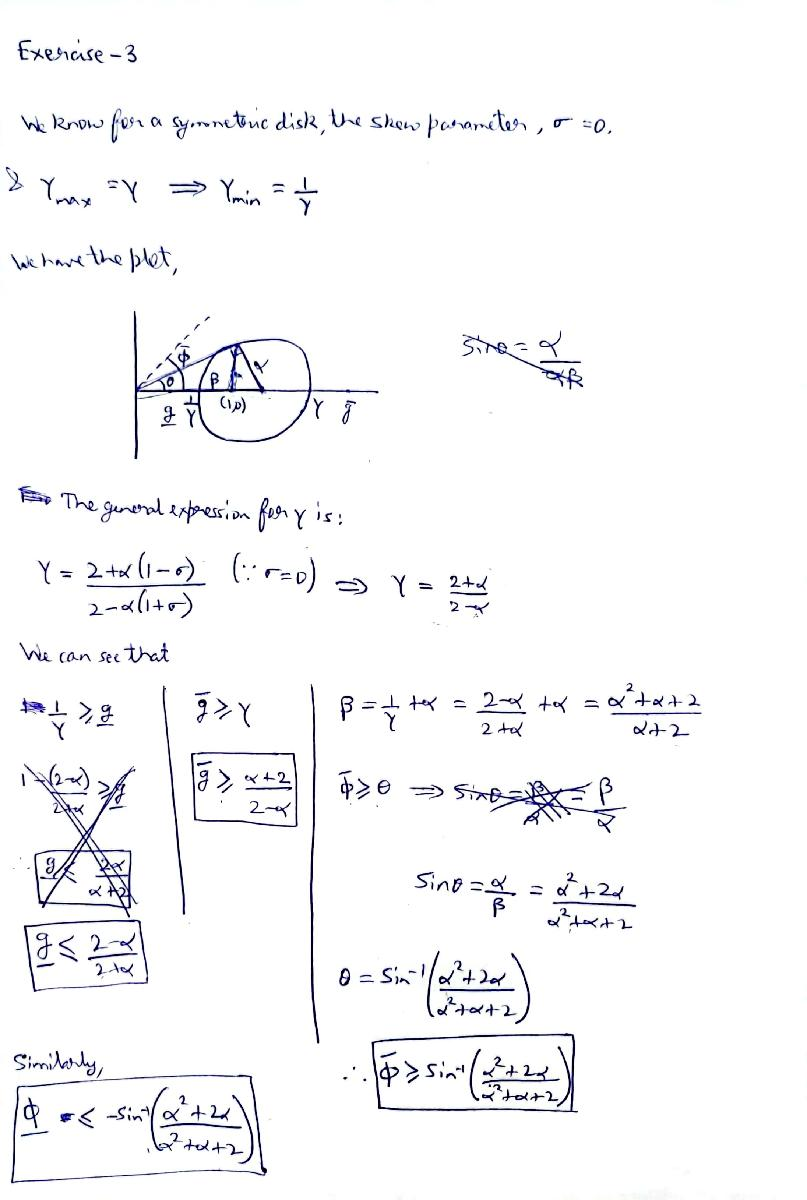

### Exercise 4 

clear all
clc
close all

s = tf('s');


for time = [5,60,100]
    
    G = 1/(s^3 + 20*s^2 +5*s - pi);
    occurrences = [];
    lambda = [];
    for t=1:time
        DGM = diskmargin(G).GainMargin;
        DPM = diskmargin(G).PhaseMargin;
    
        if DGM(1)~=DGM(2) & DPM~=[0 0]
            occurrences(t) = 1;
        else
            occurrences(t) = 0;
        end
        G = feedback(G,1);
        lambda(t) = sum(occurrences)/t;
    end
    
    prob = 1;
    for i=1:time-1
        prob = prob*(1-poisspdf(1,lambda(i)));
    end
    
    X=['Probability at ',num2str(time),'min = ',num2str(prob*poisspdf(1,lambda(i+1)))];
    disp(X)
end

Probability at 5min = 0.21592
Probability at 60min = 6.3616e-12
Probability at 100min = 6.9793e-20
